# Comparison of Analog IIR Lowpass Filters

Design a 5th-order analog Butterworth lowpass filter with a cutoff frequency of 2 GHz. Multiply by $2\pi$ to convert the frequency to radians per second. Compute the frequency response of the filter at 4096 points.

fc = [13,30];
srate = 1000;
fc = fc./(srate/2);

n = 5;
[zb,pb,kb] = butter(n,fc,"bandpass");
[bb,ab] = zp2tf(zb,pb,kb);
[hb,wb] = freqs(bb,ab,4096);
gdb = -diff(unwrap(angle(hb)))./diff(wb);

Design a 5th-order Chebyshev Type I filter with the same edge frequency and 3 dB of passband ripple. Compute its frequency response.

[z1,p1,k1] = cheby1(n,3,fc,"bandpass");
[b1,a1] = zp2tf(z1,p1,k1);
[h1,w1] = freqs(b1,a1,4096);
gd1 = -diff(unwrap(angle(h1)))./diff(w1);

Design a 5th-order Chebyshev Type II filter with the same edge frequency and 30 dB of stopband attenuation. Compute its frequency response.

[z2,p2,k2] = cheby2(n,30,fc,"bandpass");
[b2,a2] = zp2tf(z2,p2,k2);
[h2,w2] = freqs(b2,a2,4096);
gd2 = -diff(unwrap(angle(h2)))./diff(w2);

Design a 5th-order elliptic filter with the same edge frequency, 3 dB of passband ripple, and 30 dB of stopband attenuation. Compute its frequency response.

[ze,pe,ke] = ellip(n,3,30,2*pi*fc,"bandpass");
[be,ae] = zp2tf(ze,pe,ke);
[he,we] = freqs(be,ae,4096);
gde = -diff(unwrap(angle(he)))./diff(we);

Design a 5th-order Bessel filter with the same edge frequency. Compute its frequency response.

[zf,pf,kf] = besself(n,2*pi*fc(2));
[bf,af] = zp2tf(zf,pf,kf);
[hf,wf] = freqs(bf,af,4096);
gdf = -diff(unwrap(angle(hf)))./diff(wf);

Plot the attenuation in decibels. Express the frequency in gigahertz. Compare the filters.

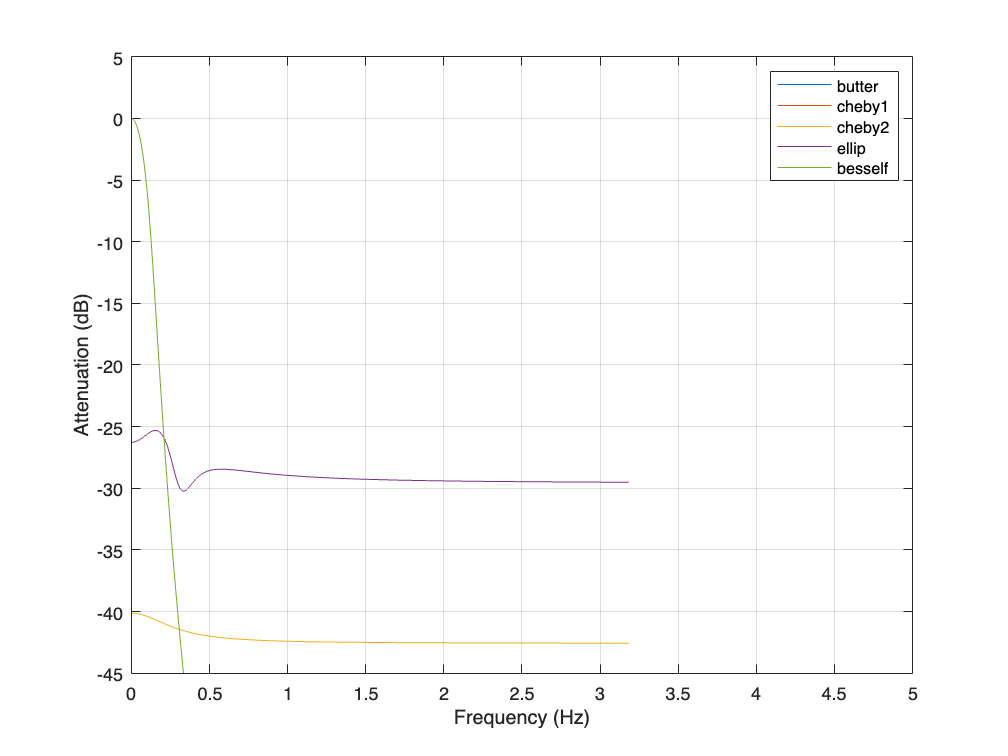

f = [wb w1 w2 we wf]/pi;
plot(f, mag2db(abs([hb h1 h2 he hf])))
axis([0 5 -45 5])
grid
xlabel("Frequency (Hz)")
ylabel("Attenuation (dB)")
legend(["butter" "cheby1" "cheby2" "ellip" "besself"])

The Butterworth and Chebyshev Type II filters have flat passbands and wide transition bands. The Chebyshev Type I and elliptic filters roll off faster but have passband ripple. The frequency input to the Chebyshev Type II design function sets the beginning of the stopband rather than the end of the passband. The Bessel filter has approximately constant group delay along the passband.

*Copyright 2022 The MathWorks, Inc.*

Plot the group delay in samples. Express the frequency in gigahertz and the group delay in nanoseconds. Compare the filters.

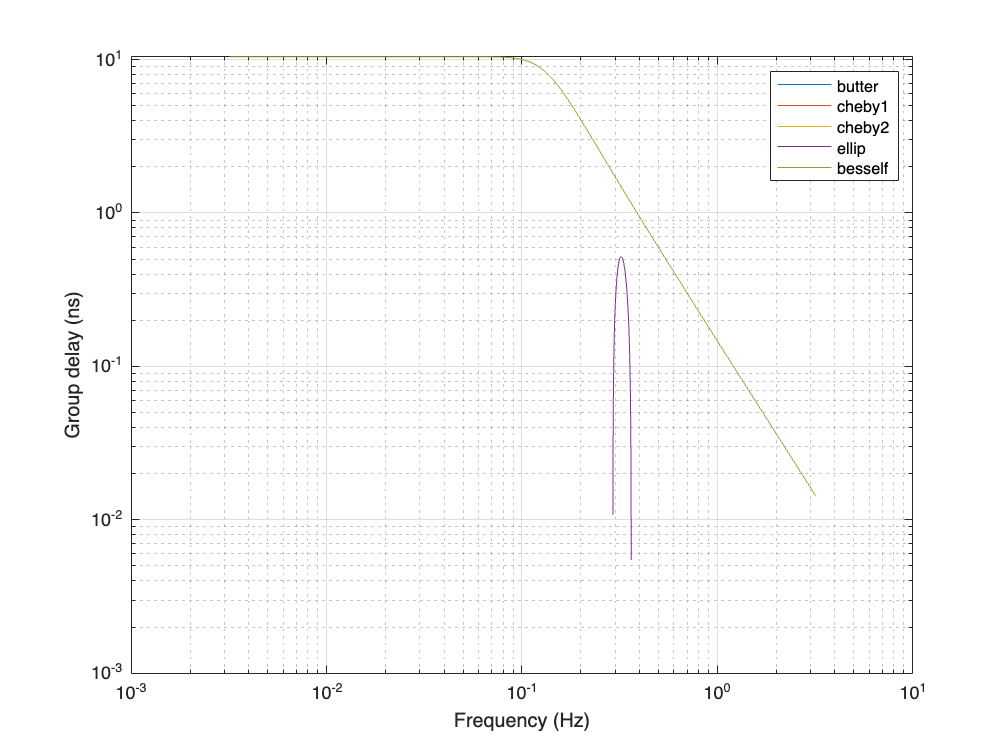

gdns = [gdb gd1 gd2 gde gdf];
gdns(gdns<0) = NaN;
loglog(f(2:end,:),gdns)
grid on
xlabel("Frequency (Hz)")
ylabel("Group delay (ns)")
legend(["butter" "cheby1" "cheby2" "ellip" "besself"])